# Sesión 5. Codificador CELP: mejoras.

## Tarea 1: Ponderación perceptual del error

#### Ilustrad el funcionamiento del codificador con figuras debidamente comentadas (fragmentos representativos de formas de onda, contribuciones adaptativa y estocástica, evolución de las ganancias, etc.)

#### Comparad el funcionamiento, en términos de SNR global, SNRseg y SNRm, utilizando tramas de 160 y 240 muestras (con subtramas de 40 y 60 muestras, respectivamente) con distintas voces. 

## TEST

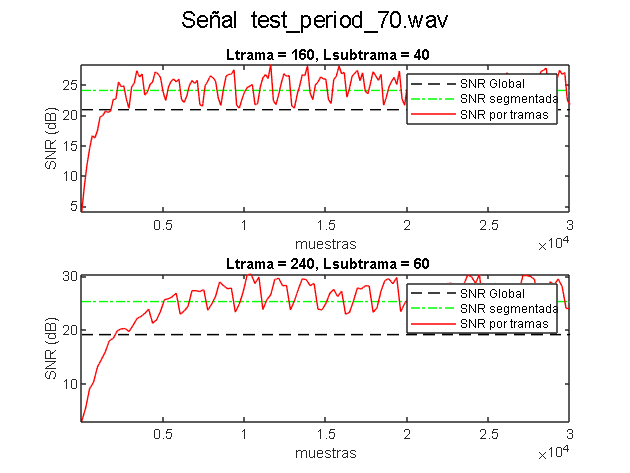

% CON 160 MUESTRAS Y VENTANA DE 40
[s, fs] = audioread("test_period_70.wav");
Ltrama = 160; 
Lsubtrama = 40;
p = 10;
display = 0;    % 0 para que se ejecute todo el codigo 
                % 1 para ver las graficas

[sh_full,B,G,AK,Tv,indv, bits_muestra]= celp_mejorado(s, Ltrama, Lsubtrama, p, display);

sh_full = sh_full';

% longitud de la señal reconstruida ajustada a la original.
sh_full=sh_full(1:length(s));


% sh, señal de voz reconstruida
% B y G vectores con las ganancias adaptativa y estocástica de las
% distintas subtramas
% Ak, matriz con los LPC de cada trama
% bits_muestra, número de bits por muestra.
% s, señal de voz
% Tv, vector con los distintos valores de T en la excitación adaptativa.
% indv, vector con los distintos índices seleccionados de la excitación estocástica.
% Ltrama y Lsubtrama, longitudes de trama y subtrama.
% p, orden de predicción.

SNRglobal = SNR(s, sh_full);

[SNRseg, SNRm, m] = SNRportramas(s,sh_full,Ltrama);

num_muestras = 1:length(s);
snr_vector = ones(size(num_muestras))*SNRglobal;
SNRseg_vector = ones(size(num_muestras))*SNRseg;
SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));

figure(2);
subplot(2,1,1),plot(num_muestras,snr_vector,'--k',num_muestras,SNRseg_vector,'-.g',num_muestras,SNRm_interp,'-r');
axis tight;
xlabel('muestras');
ylabel('SNR (dB)');
title(' Ltrama = 160, Lsubtrama = 40');
legend('SNR Global', 'SNR segmentada', 'SNR por tramas');
axis tight;

% CON 240 MUESTRAS Y VENTANA DE 60

Ltrama = 240; 
Lsubtrama = 60;
p = 10;
display = 0;    % 0 para que se ejecute todo el codigo 
                % 1 para ver las graficas

[sh_full,B,G,AK,Tv,indv, bits_muestra]= celp_mejorado(s, Ltrama, Lsubtrama, p, display);

sh_full = sh_full';

% longitud de la señal reconstruida ajustada a la original.
sh_full=sh_full(1:length(s));


% sh, señal de voz reconstruida
% B y G vectores con las ganancias adaptativa y estocástica de las
% distintas subtramas
% Ak, matriz con los LPC de cada trama
% bits_muestra, número de bits por muestra.
% s, señal de voz
% Tv, vector con los distintos valores de T en la excitación adaptativa.
% indv, vector con los distintos índices seleccionados de la excitación estocástica.
% Ltrama y Lsubtrama, longitudes de trama y subtrama.
% p, orden de predicción.

SNRglobal = SNR(s, sh_full);

[SNRseg, SNRm, m] = SNRportramas(s,sh_full,Ltrama);

num_muestras = 1:length(s);
snr_vector = ones(size(num_muestras))*SNRglobal;
SNRseg_vector = ones(size(num_muestras))*SNRseg;
SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));

figure(2);
subplot(2,1,2),plot(num_muestras,snr_vector,'--k',num_muestras,SNRseg_vector,'-.g',num_muestras,SNRm_interp,'-r');
axis tight;
xlabel('muestras');
ylabel('SNR (dB)');
title(' Ltrama = 240, Lsubtrama = 60');
legend('SNR Global', 'SNR segmentada', 'SNR por tramas');
sgtitle('Señal test\_period\_70.wav');
axis tight;

## GALA

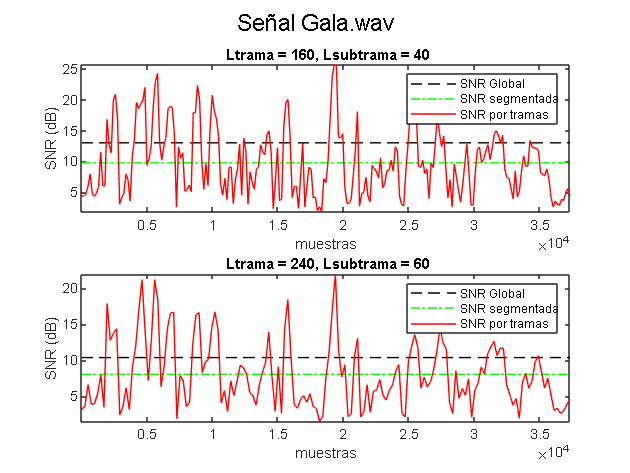

% CON 160 MUESTRAS Y VENTANA DE 40
[s, fs] = audioread("Gala_8khz.wav");
Ltrama = 160; 
Lsubtrama = 40;
p = 10;
display = 0;    % 0 para que se ejecute todo el codigo 
                % 1 para ver las graficas

[sh_full,B,G,AK,Tv,indv, bits_muestra]= celp_mejorado(s, Ltrama, Lsubtrama, p, display);

sh_full = sh_full';

% longitud de la señal reconstruida ajustada a la original.
sh_full=sh_full(1:length(s));


% sh, señal de voz reconstruida
% B y G vectores con las ganancias adaptativa y estocástica de las
% distintas subtramas
% Ak, matriz con los LPC de cada trama
% bits_muestra, número de bits por muestra.
% s, señal de voz
% Tv, vector con los distintos valores de T en la excitación adaptativa.
% indv, vector con los distintos índices seleccionados de la excitación estocástica.
% Ltrama y Lsubtrama, longitudes de trama y subtrama.
% p, orden de predicción.

SNRglobal = SNR(s, sh_full);

[SNRseg, SNRm, m] = SNRportramas(s,sh_full,Ltrama);

num_muestras = 1:length(s);
snr_vector = ones(size(num_muestras))*SNRglobal;
SNRseg_vector = ones(size(num_muestras))*SNRseg;
SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));

figure(2);
subplot(2,1,1),plot(num_muestras,snr_vector,'--k',num_muestras,SNRseg_vector,'-.g',num_muestras,SNRm_interp,'-r');
axis tight;
xlabel('muestras');
ylabel('SNR (dB)');
title(' Ltrama = 160, Lsubtrama = 40');
legend('SNR Global', 'SNR segmentada', 'SNR por tramas');
axis tight;

%  CON 240 MUESTRAS Y VENTANA DE 60
Ltrama = 240; 
Lsubtrama = 60;
p = 10;
display = 0;    % 0 para que se ejecute todo el codigo 
                % 1 para ver las graficas

[sh_full,B,G,AK,Tv,indv, bits_muestra]= celp_mejorado(s, Ltrama, Lsubtrama, p, display);

sh_full = sh_full';

% longitud de la señal reconstruida ajustada a la original.
sh_full=sh_full(1:length(s));


% sh, señal de voz reconstruida
% B y G vectores con las ganancias adaptativa y estocástica de las
% distintas subtramas
% Ak, matriz con los LPC de cada trama
% bits_muestra, número de bits por muestra.
% s, señal de voz
% Tv, vector con los distintos valores de T en la excitación adaptativa.
% indv, vector con los distintos índices seleccionados de la excitación estocástica.
% Ltrama y Lsubtrama, longitudes de trama y subtrama.
% p, orden de predicción.

SNRglobal = SNR(s, sh_full);

[SNRseg, SNRm, m] = SNRportramas(s,sh_full,Ltrama);

num_muestras = 1:length(s);
snr_vector = ones(size(num_muestras))*SNRglobal;
SNRseg_vector = ones(size(num_muestras))*SNRseg;
SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));

figure(2);
subplot(2,1,2),plot(num_muestras,snr_vector,'--k',num_muestras,SNRseg_vector,'-.g',num_muestras,SNRm_interp,'-r');
axis tight;
xlabel('muestras');
ylabel('SNR (dB)');
title(' Ltrama = 240, Lsubtrama = 60');
sgtitle('Señal Gala.wav');
legend('SNR Global', 'SNR segmentada', 'SNR por tramas');
axis tight;

## AFONSO

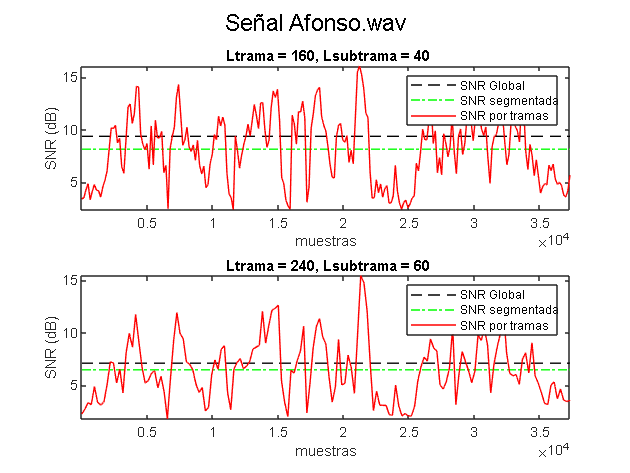

% CON 160 MUESTRAS Y VENTANA DE 40
[s, fs] = audioread("Afonso_8khz.wav");
Ltrama = 160; 
Lsubtrama = 40;
p = 10;
display = 0;    % 0 para que se ejecute todo el codigo 
                % 1 para ver las graficas

[sh_full,B,G,AK,Tv,indv, bits_muestra]= celp_mejorado(s, Ltrama, Lsubtrama, p, display);

sh_full = sh_full';

% longitud de la señal reconstruida ajustada a la original.
sh_full=sh_full(1:length(s));


% sh, señal de voz reconstruida
% B y G vectores con las ganancias adaptativa y estocástica de las
% distintas subtramas
% Ak, matriz con los LPC de cada trama
% bits_muestra, número de bits por muestra.
% s, señal de voz
% Tv, vector con los distintos valores de T en la excitación adaptativa.
% indv, vector con los distintos índices seleccionados de la excitación estocástica.
% Ltrama y Lsubtrama, longitudes de trama y subtrama.
% p, orden de predicción.

SNRglobal = SNR(s, sh_full);

[SNRseg, SNRm, m] = SNRportramas(s,sh_full,Ltrama);

num_muestras = 1:length(s);
snr_vector = ones(size(num_muestras))*SNRglobal;
SNRseg_vector = ones(size(num_muestras))*SNRseg;
SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));

figure(2);
subplot(2,1,1),plot(num_muestras,snr_vector,'--k',num_muestras,SNRseg_vector,'-.g',num_muestras,SNRm_interp,'-r');
axis tight;
xlabel('muestras');
ylabel('SNR (dB)');
title(' Ltrama = 160, Lsubtrama = 40');
legend('SNR Global', 'SNR segmentada', 'SNR por tramas');
axis tight;

%  CON 240 MUESTRAS Y VENTANA DE 60
Ltrama = 240; 
Lsubtrama = 60;
p = 10;
display = 0;    % 0 para que se ejecute todo el codigo 
                % 1 para ver las graficas

[sh_full,B,G,AK,Tv,indv, bits_muestra]= celp_mejorado(s, Ltrama, Lsubtrama, p, display);

sh_full = sh_full';

% longitud de la señal reconstruida ajustada a la original.
sh_full=sh_full(1:length(s));


% sh, señal de voz reconstruida
% B y G vectores con las ganancias adaptativa y estocástica de las
% distintas subtramas
% Ak, matriz con los LPC de cada trama
% bits_muestra, número de bits por muestra.
% s, señal de voz
% Tv, vector con los distintos valores de T en la excitación adaptativa.
% indv, vector con los distintos índices seleccionados de la excitación estocástica.
% Ltrama y Lsubtrama, longitudes de trama y subtrama.
% p, orden de predicción.

SNRglobal = SNR(s, sh_full);

[SNRseg, SNRm, m] = SNRportramas(s,sh_full,Ltrama);

num_muestras = 1:length(s);
snr_vector = ones(size(num_muestras))*SNRglobal;
SNRseg_vector = ones(size(num_muestras))*SNRseg;
SNRm_interp = interp1(1:length(SNRm), SNRm, linspace(1, length(SNRm), length(num_muestras)));

figure(2);
subplot(2,1,2),plot(num_muestras,snr_vector,'--k',num_muestras,SNRseg_vector,'-.g',num_muestras,SNRm_interp,'-r');
axis tight;
xlabel('muestras');
ylabel('SNR (dB)');
title(' Ltrama = 240, Lsubtrama = 60');
sgtitle('Señal Afonso.wav');
legend('SNR Global', 'SNR segmentada', 'SNR por tramas');
axis tight;